% Ustawienia formatu staloprzecinkowego
sign = 1;     % 1 = signed
prec_i = 0;   % liczba bitow czesci calkowitej
prec_f = 17;  % liczba bitow czesci ulamkowej
word = sign + prec_i + prec_f;

% wsp i ich wartosci
nazwy = {'Y1', 'Y2', 'Y3', 'Cb1', 'Cb2', 'Cb3', 'Cr1', 'Cr2', 'Cr3'};
wartosci = [0.299, 0.587, 0.114, -0.168736, -0.331264, 0.5, 0.5, -0.418688, -0.081312];

% przetwarzanie
for i = 1:length(nazwy)
    eval([nazwy{i}, '_stalo = fi(wartosci(i), sign, word, prec_f);']);
    bin_str = eval(['bin(', nazwy{i}, '_stalo);']);
    disp([nazwy{i}, ' binarnie: ', bin_str]);
end

Y1 binarnie: 001001100100010111
Y2 binarnie: 010010110010001011
Y3 binarnie: 000011101001011110
Cb1 binarnie: 111010100110011011
Cb2 binarnie: 110101011001100101
Cb3 binarnie: 010000000000000000
Cr1 binarnie: 010000000000000000
Cr2 binarnie: 110010100110100010
Cr3 binarnie: 111101011001011110


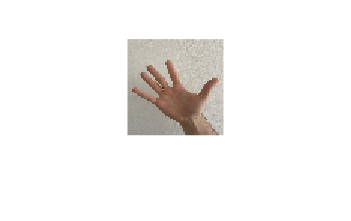

%% wczytanie normalnego obrazu i poddanie go operacji
obraz = double(imread("dlon.ppm"));
figure;
imshow(obraz / 255);

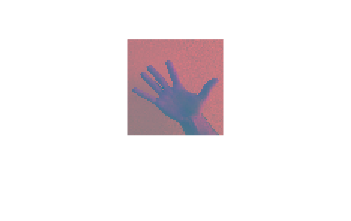


R = obraz(:,:,1);
G = obraz(:,:,2);
B = obraz(:,:,3);

R = R(:)';
G = G(:)';
B = B(:)';

%% Parametry formatu
% Źródłowy (8 bitów int, 0 frac)
sign_src = 1;
prec_i_src = 8;
prec_f_src = 0;
word_src = sign_src + prec_i_src + prec_f_src;

% Docelowy (8 bitów int, 0 frac)
sign_dst = 1;
prec_i_dst = 8;
prec_f_dst = 0;
word_dst = sign_dst + prec_i_dst + prec_f_dst;

% Konwersja kanałów RGB do fixed-point
Rs = fi(R, sign_src, word_src, prec_f_src);
Gs = fi(G, sign_src, word_src, prec_f_src);
Bs = fi(B, sign_src, word_src, prec_f_src);
typ_docelowy = fi(0,sign_src,word_src,prec_f_src);

%% Operacja Y, Cb, Cr
Y_stalo = quantize(Y1_stalo*Rs, sign_dst, word_dst, prec_f_dst) + ...
          quantize(Y2_stalo*Gs, sign_dst, word_dst, prec_f_dst) + ...
          quantize(Y3_stalo*Bs, sign_dst, word_dst, prec_f_dst);

Cb_stalo = quantize(Cb1_stalo*Rs, sign_dst, word_dst, prec_f_dst) + ...
           quantize(Cb2_stalo*Gs, sign_dst, word_dst, prec_f_dst) + ...
           quantize(Cb3_stalo*Bs, sign_dst, word_dst, prec_f_dst) + 128*ones(1,length(R));

Cr_stalo = quantize(Cr1_stalo*Rs, sign_dst, word_dst, prec_f_dst) + ...
           quantize(Cr2_stalo*Gs, sign_dst, word_dst, prec_f_dst) + ...
           quantize(Cr3_stalo*Bs, sign_dst, word_dst, prec_f_dst) + 128*ones(1,length(R));

%% obraz w matlabie po operacjach
YCbCr_stalo = cat(3, double(reshape(Y_stalo,  64, 64)), double(reshape(Cb_stalo, 64, 64)), double(reshape(Cr_stalo, 64, 64)));
figure;
imshow(YCbCr_stalo / 255);

%% obraz z symulacji vivado
vivado = double(imread("out_10.ppm"));
figure;
imshow(vivado / 255);


%% roznica 
diff_sim = imabsdiff(YCbCr_stalo,vivado)

diff_sim = diff_sim(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

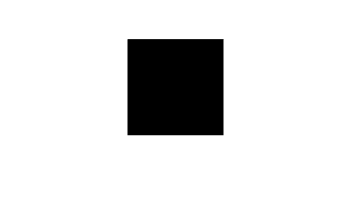

figure;
imshow(diff_sim / 255);